% ANOVA Testing

%algs = ["iTAML", "RPSnet", "DGR", "foster", "memo", "der"];
algorithm = 'iTAML'

algorithm = 'iTAML'

Class 1 95% CI: [0.284920, 0.309939]
Class 2 95% CI: [0.318235, 0.343360]


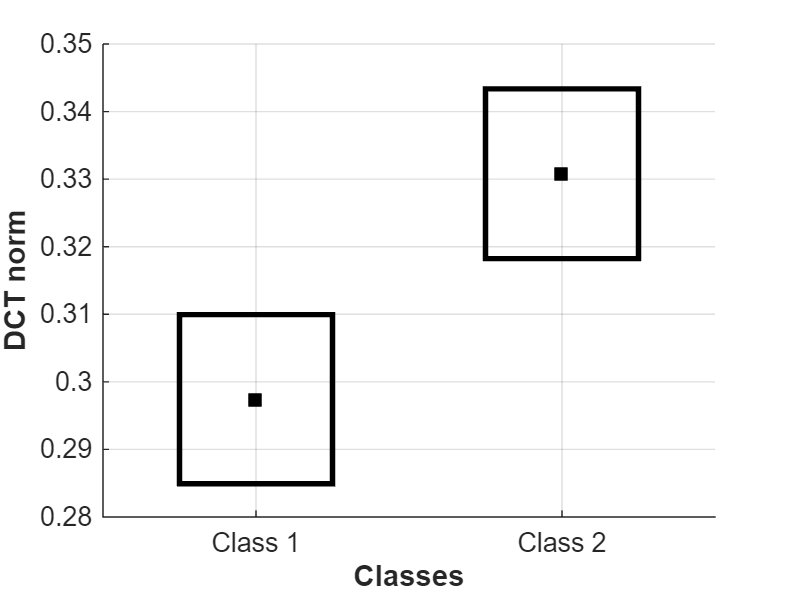

p_value = 3.6984e-04

CI_class1 =     0.2849    0.3099


CI_class2 =     0.3182    0.3434


dataset = 'mnist';

% Get JSDs
jsd_struct = load(sprintf("%s\\%s\\inclass_jsd.mat", algorithm, dataset));
scn1_jsds = [];
scn2_jsds = [];

for i=1:length(fieldnames(jsd_struct))
    scn1_jsds = [scn1_jsds getfield(jsd_struct, sprintf('t%d', i)).scn1];
    scn2_jsds = [scn2_jsds getfield(jsd_struct, sprintf('t%d', i)).scn2];
end


% Perform ANOVA
[p_value,CI_class1,CI_class2] = anova1_class1_class2(scn1_jsds, scn2_jsds)



%{
Evaluate Results
Ho: There are no significant differences between the means
 of scn1 and scn2 JSDs.

p-value:
If p > alpha: Null hypothesis is accepted
If p < alpha: Null hypothesis is rejected

If confidence value is 95%, alpha = 0.05


%}
